# Bike Frequency

## Initialization and Display of Raw Data

Reading from `freqs.csv` into time and bike arrays

a = textscan(fopen("freqs.csv"), '%s %d', 'Delimiter',',');
time = a{1};
bikes = a{2};
if size(bikes) ~= size(time)
    disp('oh snap, invalid sizes')
end

Finding total and accumulating count of bikes

total = sum(bikes);
disp(strcat('In total, ', string(total), ...
    ' bikes passed during 30 minutes'))

In total,78 bikes passed during 30 minutes


disp(strcat('That means 𝜆=', string(total / 30), ...
    ' bikes pass on average every minute'))

That means 𝜆=2.6 bikes pass on average every minute


bikes = cumsum(bikes);

Converting strings to `MATLAB` timestamps

time = datetime(time, 'Format','mm:ss');

Plotting a graph

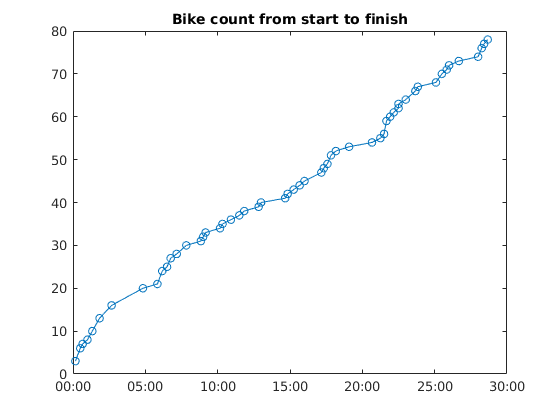

plot(datenum(time), bikes, '-o')
title('Bike count from start to finish')
datetick('x', 'MM:SS')

## Poisson Distribution

### With t = 1 minute

– lower reliability

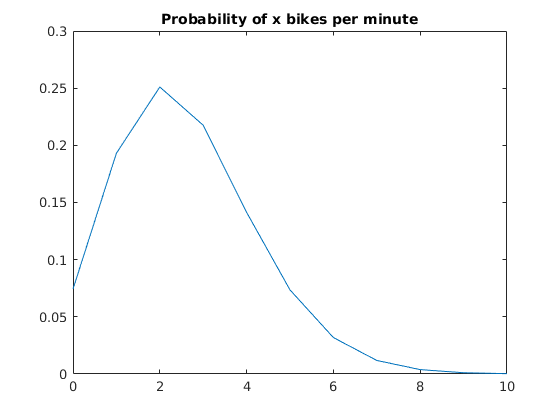

lambda = total / 30;
x = 0:10;
plot(x, poisspdf(x,lambda))
title('Probability of x bikes per minute')

### With t = 30 minutes

– which matches the circumstances of our original data

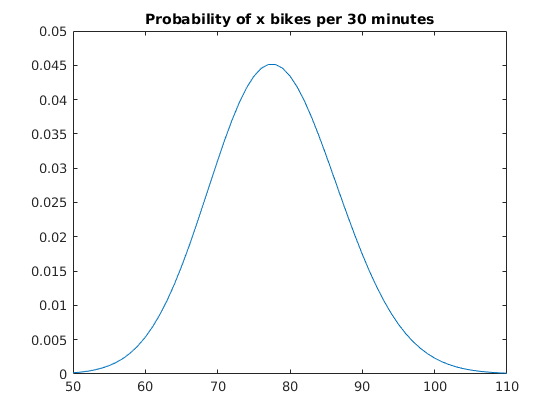

lambda = total;
x = 50:110;
plot(x, poisspdf(x,lambda))
title('Probability of x bikes per 30 minutes')